Some initial particle positions are not between bounds lb and ub; PARTICLESWARM
shifted them to satisfy the bounds.
                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              30          0.5697           1.761        0
    1              60          0.5697           2.425        0    2              90          0.5697           2.381        1
    3             120          0.5697           1.518        2    4             150          0.5697           1.431        3
    5             180          0.5697            1.42        4    6             210          0.5697           1.169        5
    7             240          0.5697            1.03        6    8             270          0.5697           1.207        7
    9             300          0.5697           0.904        8   10             330          0.5697           1.072        9
   11             360          0.5697          0.9512       10

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


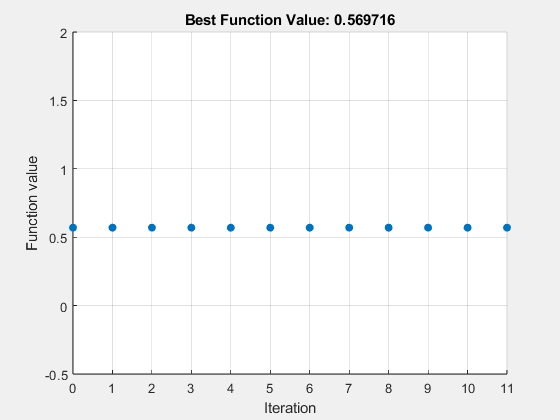

% Set nondefault solver options
options = optimoptions("particleswarm","InitialPoints",K_start,...
    "InertiaRange",Inertia_range,"InitialSwarmSpan",Initial_swarm_span,...
    "MaxIterations",100,"MaxStallIterations",10,"Display","iter","PlotFcn",...
    "pswplotbestf");

% Solve
[K_sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options);


% Clear variables
clearvars options